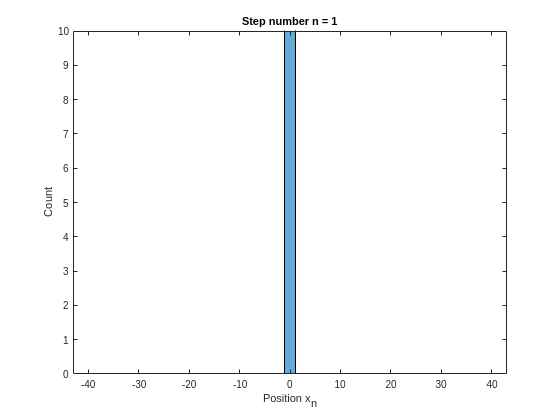

% Initialisation
clear

% Reference
particles = 100;   % number of particles
steps     = 200;    % number of steps
p         = 0.5;    % probability of jumping left
Delta     = 1;      % size of jump

x = zeros(particles,steps+1); % initial locations

% Simulation
for n = 1:steps
    for m = 1:particles
        r = rand;   % random number between 0 and 1
        if r < p
            x(m, n+1) = x(m, n) - Delta;    % jump left
        else
            x(m, n+1) = x(m, n) + Delta;    % jump right
        end
    end
end

% Animation
figure
L = max(abs(x(:))); % the furthest the particles reached
for n = 1:steps+1
    histogram(x(:,n), -L:2*Delta:L);
    axis([-L, L, 0, particles/10]);
    xlabel('Position x_n');
    ylabel('Count');
    title(['Step number n = ', num2str(n)]);
    drawnow
end